# BinomialDistribution

Plots the binomial distribution for select parameters and examines fluctuations by simulating experiments with a biased coin.

Author: Duncan Carlsmith

Clear variables and close all open figure windows if you would like.

%clear;delete(findall(0,'Type','figure'))

### Plot binomial distribution for a few values of the number of trials.

Create figures.

MATLAB plotting and other commands generally create a new figure if needed automatically if none exist and overwrite the present figure if it exists, or add to the present figure if a hold on command has been issued. Sometimes one wants a bit more control to add to figures nonsequentially and hence to refere to figures by name.

f1=figure;f2=figure; 

Define an irregular array of values for the number trials to  defining various binomial distributions. Think of these as the number of coin flips.

**Try this**: Add to or adjust this array if you would like.

ntrials=[25,15,5];

Loop over values for the number of trials.

for whichsample=1:3
n=ntrials(whichsample);

Pick a probability for one of the two outcomes, heads say.

**Try this**: Play with the value. P=1/2 for a fair coin.

p=.6;

The number of successes ranges from 0 to n.

x = 0:n;

The MATLAB function [binopdf](https://www.mathworks.com/help/stats/binopdf.html) generates the probabilities for all outcomes.

y = binopdf(x,n,p);

Select the first figure.

figure(f1)

Plot in the first figure this probability distribution. Rather than use [plot](https://www.mathworks.com/help/matlab/ref/plot.html) which creates points, use [bar](https://www.mathworks.com/help/matlab/ref/bar.html) to make a bar chart.

%plot(x,y,'+-');hold on
bar(x,y);hold on
title('Binomial distribution for fixed p=0.6, variable n');
xlabel('Number of occurances')
ylabel('Probability')

The probability distribution approaches a normal distribution for a large number of trials. Plot in the 2nd figure the natural logarithm of the probability distribution values. (Another way to present the logarthim of values is to use [semilogy](https://www.mathworks.com/help/matlab/ref/semilogy.html).) The logarithm of a normal distribution is an inverted parabola so the results should lokk like inverted parabolas.

figure(f2)
plot(x,log(y),'+-');hold on
title('Binomial distribution for p=0.6 (log scale)');
xlabel('Number of occurpances')
ylabel('Logarithm of probability')
end
figure(f1)

If you change the number of trials vector, you will want to change the values in the following legend. The legend creation can be programmed to use the array and put in the correct values automatically but for simplicity we will simple "hard code" the values into the legend command.

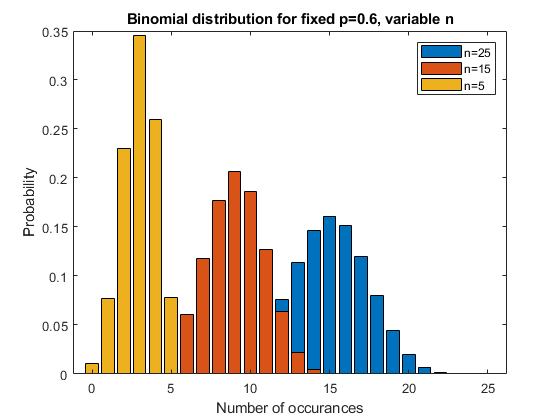

legend('n=25','n=15','n=5')

Return to the 2nd figure and add a legend.

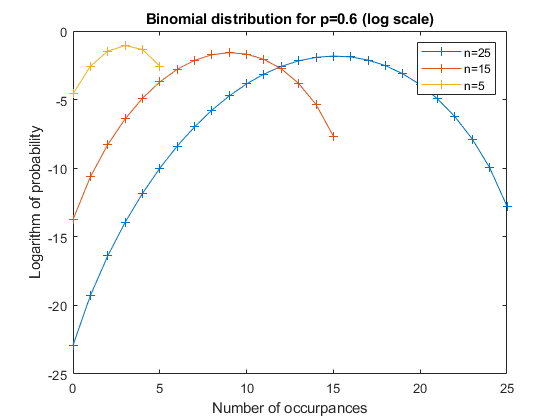

figure(f2)
legend('n=25','n=15','n=5')

### Simulate a set of experiments and plot the results.

Suppose someone tosses a coin ntrials times and observes some number of heads n. Now repeat the experiment nexperiments times and plot the frequency of occurrance of each n. It will look like the binomial distrbution but not be exactly the binomial distribution. Now suppose npeople do this and superpose the histograms to see how their results would compare. This gives a sense of the fluctuations.

([Alternate code](https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/9554/versions/5/previews/numerical-tour/toolbox_general/binornd.m/index.html?access_key= ).)

Create a new figure.

figure;

Set parameters for the simulated experiments.

p=.6;
ntrial=30;
nexperiments=100;
npeople=3;
for ii=1:npeople

We use the function [binornd](https://www.mathworks.com/help/stats/binornd.html) to generate a random sample from the binomial distribution.

x=binornd(ntrial,p,nexperiments,1);

Histogram the distribution of results, using a stair step style so different results do not hide each other.

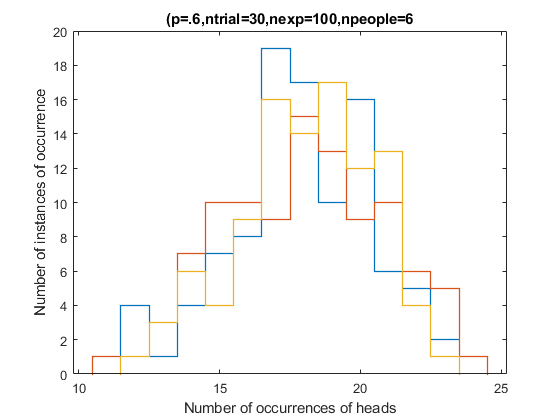

h=histogram(x);hold on
h.DisplayStyle='stairs';
h.LineWidth=1;
end
title('(p=.6,ntrial=30,nexp=100,npeople=6')
xlabel('Number of occurrences of heads')
ylabel('Number of instances of occurrence')